## Read and filter the data 

Including location derivatives dx/dt and dy/dt in columns 25 and 26 respectively.

clear all, close all;
temp = csvread('trajectories-0830-0845-data_vel_2.csv');
train_clustering = temp(temp(:, 6) >= 352 & temp(:, 6)< 430 & temp(:, 5)> -5 & temp(:, 5) < 85 , :);
train_clustering = train_clustering(train_clustering(:,1) ~= 274 & train_clustering(:,1) ~= 543 & train_clustering(:,1) ~= 639, :);
train_clustering = train_clustering(train_clustering(:,1) ~= 1317 & train_clustering(:,1) ~= 794 & train_clustering(:,1) ~= 651, :);
scatter(train_clustering(:,5),train_clustering(:,6), 'g.', 'MarkerEdgeAlpha', 0.2 , 'MarkerFaceAlpha', 0.2);
axis manual equal;
xlabel('X [ft]');
ylabel('Y [ft]');
clear temp;


## Generating clustering input data 

unique_IDs = unique(train_clustering(:,1));
numOfVeh = size(unique_IDs, 1);
start_end = zeros(numOfVeh,9);
for i =1:numOfVeh
    a = train_clustering(train_clustering(:,1) == unique_IDs(i),:);
    start_end(i,1) = unique_IDs(i);
    start_end(i,2:3) = a(1,5:6);
    start_end(i,4:5) = a(end,5:6);
    start_end(i,6:7) = a(1,25:26);
    start_end(i,8:9) = a(end,25:26);
end

## Clustering

number_of_clusters = 8;

[clusters, centers] = kmeans(start_end(:,2:5),number_of_clusters);
% clusters = clusterdata(start_end(:,2:5), 'distance', 'Euclidean', 'linkage' , 'average', 'cutoff', 0.2);
clusters = [clusters , start_end(:,1)];
keySet = clusters(:,2);
valueSet = clusters(:,1);
id_cluster_map = containers.Map(keySet,valueSet);

## Concating the cluster number as the last column of the data

for i =1:size(train_clustering,1)
    train_clustering(i,27) = id_cluster_map(train_clustering(i,1));
end

## Plotting different clusters 

MarkerEdgeAlpha = 0.8;
scatter(train_clustering(train_clustering(:,27) == 1,5),train_clustering(train_clustering(:,27) == 1,6), 'b^', 'MarkerFaceColor', 'blue');
hold on;
scatter(train_clustering(train_clustering(:,27) == 2,5),train_clustering(train_clustering(:,27) == 2,6), 'r+', 'MarkerFaceColor', 'red');
hold on;
scatter(train_clustering(train_clustering(:,27) == 3,5),train_clustering(train_clustering(:,27) == 3,6), 'c*', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 4,5),train_clustering(train_clustering(:,27) == 4,6), 'g^', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 5,5),train_clustering(train_clustering(:,27) == 5,6), 'mx', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 6,5),train_clustering(train_clustering(:,27) == 6,6), 'y.' , 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 7,5),train_clustering(train_clustering(:,27) == 7,6), 'k', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 8,5),train_clustering(train_clustering(:,27) == 8,6), 'm*', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 9,5),train_clustering(train_clustering(:,27) == 9,6), 'k*', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 10,5),train_clustering(train_clustering(:,27) == 10,6), 'b.', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 11,5),train_clustering(train_clustering(:,27) == 11,6), 'r', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
axis manual equal;
xlabel('X [ft]');
ylabel('Y [ft]');
hold off;

# Training 

for cluster = 1:number_of_clusters
    cluster
    if (cluster == 4 || cluster == 5)
        continue;
    end
    temp = train_clustering(train_clustering(:,27) == cluster, :);
    unique_IDs = unique(temp(:,1));
    numOfVeh = size(unique_IDs, 1);
    train = [];
    for i =1:min(10,numOfVeh)
        train= [train;temp(temp(:,1) == unique_IDs(i),:)];
    end
    
    % Preparing the GP parameters and hyperparameters
    covfunc = @covSEiso;
    likfunc = @likGauss; sn = 0.1; hyp.lik = log(sn);
    
    % Running GP for vx
    hyp_vx(cluster).cov = [0 ; 0];
    hyp_vx(cluster).lik = log(0.1);
    hyp_vx(cluster) = minimize(hyp_vx(cluster), @gp, -100, @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25));
    exp(hyp_vx(cluster).lik);
    nlml_vx = gp(hyp_vx(cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25));
    
    % Running GP for vy
    hyp_vy(cluster).cov = [0 ; 0];
    hyp_vy(cluster).lik = log(0.1);
    hyp_vy(cluster) = minimize(hyp_vy(cluster), @gp, -100, @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26));
    exp(hyp_vy(cluster).lik);
    nlml_vy = gp(hyp_vy(cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26));
    %end
end

# Testing without maneuver detection

num_of_test_trajs = 10;
num_of_train_trajs = 10;
start_time = 10;
end_time = 40;

% Euclidean Distances
% 3-D matrices
error_gp1 = zeros(number_of_clusters,num_of_test_trajs, end_time);
error_gp2 = zeros(number_of_clusters,num_of_test_trajs, end_time);
error_dyn = zeros(number_of_clusters,num_of_test_trajs, end_time);
erro_ave_gp = zeros(number_of_clusters,num_of_test_trajs,end_time);
error_ave_gp_dyn = zeros(number_of_clusters,num_of_test_trajs,end_time);
error_ave_gp2_dyn = zeros(number_of_clusters,num_of_test_trajs,end_time);

for cluster = 1:number_of_clusters
    cluster
    if cluster == 4 || cluster == 5
        continue
    end
    temp = train_clustering(train_clustering(:,27) == cluster, :);
    unique_IDs = unique(temp(:,1));
    numOfVeh = size(unique_IDs, 1);
    
    train = [];
    for i =1:min(num_of_train_trajs,numOfVeh)
        train= [train;temp(temp(:,1) == unique_IDs(i),:)];
    end
    
    test = [];
    figure
    start_traj = num_of_train_trajs + 1;
    end_traj = num_of_test_trajs + num_of_train_trajs;
    for i = start_traj : min(end_traj,numOfVeh) % trajectories from each cluster for testing
        test= temp(temp(:,1) == unique_IDs(i),:);
        scatter(test(:,5),test(:,6), 'b.');
        hold on;
        
        steps = size(test,1);
        steps = min(end_time,steps);
        [m_vx s_vx]= gp(hyp_vx(cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25),test(1:steps,5:6));
        [m_vy s_vy] = gp(hyp_vy(cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26),test(1:steps,5:6));
        
        if size(test,1) < 11
            continue
        end
        
        % Initialization of position, velocity and acceleration
        p = [test(start_time,5),test(start_time,6)];
        v = [test(start_time,25),test(start_time,26)];
        a = [test(start_time,25) - test(start_time - 1,25) , test(start_time,26) - test(start_time - 1,26)];
        
        p_gp_1 = p;
        p_gp_2 = p;
        p_dyn = p;
        v_dyn = v;
        
        p_ave_gp = p;
        p_ave_gp_dyn = p;
        p_ave_gp2_dyn = p;
        
        for j = start_time:steps
            [m_vx_val s_vx]= gp(hyp_vx(cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25),p);
            [m_vy_val s_vy] = gp(hyp_vy(cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26),p);
            p_gp_1 = Project(p_gp_1,[m_vx_val,m_vy_val]);
            p_gp_2 = Project(p_gp_2,[m_vx(j),m_vy(j)]);
            [p_dyn,v_dyn] =  Project(p_dyn,v_dyn,a);
            p_ave_gp = mean([p_gp_1;p_gp_2]);
            p_ave_gp_dyn = mean([p_gp_1;p_gp_2;p_dyn]);
            p_ave_gp2_dyn = mean([p_gp_2;p_dyn]);
            
            %calculating Euclidean distances
            error_gp1(cluster,i-num_of_train_trajs,j) = EuclideanD(p_gp_1, test(j,5:6));
            error_gp2(cluster,i-num_of_train_trajs,j) = EuclideanD(p_gp_2, test(j,5:6));
            error_dyn(cluster,i-num_of_train_trajs,j) = EuclideanD(p_dyn, test(j,5:6));
            erro_ave_gp(cluster,i-num_of_train_trajs,j) = EuclideanD(p_ave_gp, test(j,5:6));
            error_ave_gp_dyn(cluster,i-num_of_train_trajs,j) = EuclideanD(p_ave_gp_dyn, test(j,5:6));
            error_ave_gp2_dyn(cluster,i-num_of_train_trajs,j) = EuclideanD(p_ave_gp2_dyn, test(j,5:6));
        end
        
    end
    hold off;
end

# Testing with maneuver detection

num_of_test_trajs = 10;
num_of_train_trajs = 10;
start_time = 10;
end_time = 40;

% Euclidean Distances
% 3-D matrices
error_gp1 = zeros(number_of_clusters,num_of_test_trajs, end_time);
error_gp2 = zeros(number_of_clusters,num_of_test_trajs, end_time);
error_dyn = zeros(number_of_clusters,num_of_test_trajs, end_time);
erro_ave_gp = zeros(number_of_clusters,num_of_test_trajs,end_time);
error_ave_gp_dyn = zeros(number_of_clusters,num_of_test_trajs,end_time);
error_ave_gp2_dyn = zeros(number_of_clusters,num_of_test_trajs,end_time);

for cluster = 1:number_of_clusters
    cluster
    if cluster == 4 || cluster == 5
        continue;
    end
    temp = [];
    temp = train_clustering(train_clustering(:,27) == cluster, :);
    unique_IDs = unique(temp(:,1));
    numOfVeh = size(unique_IDs, 1);
    
    
    start_traj = num_of_train_trajs + 1;
    end_traj = num_of_test_trajs + num_of_train_trajs;
    
    for i = start_traj : min(end_traj,numOfVeh) % trajectories from each cluster for testing
        % preparing the test traj
        test = [];
        test= temp(temp(:,1) == unique_IDs(i),:);
        %         scatter(test(:,5),test(:,6), 'b.');
        %         hold on;
        
        steps = size(test,1);
        steps = min(end_time,steps);
        if size(test,1) < (start_time + 1)
            continue
            % go to the next traj
        end
        
        % maneuver selection
        p_model = ones(1,number_of_clusters);
        p_model(4) = -1;
        p_model(5) = -1;
        p_model_2 = ones(1,number_of_clusters);
        p_model_2 = -1;
        lp = NaN(1,number_of_clusters);
        sd = NaN(1,number_of_clusters);
        for c = 1:number_of_clusters
            if c == 4 || c == 5
                continue;
            end
            % preparing train data of cluster c
            temp_c = train_clustering(train_clustering(:,27) == c, :);
            unique_IDs_c = unique(temp_c(:,1));
            numOfVeh_c = size(unique_IDs_c, 1);
            train = [];
            for j =1:min(num_of_train_trajs,numOfVeh_c)
                train= [train;temp_c(temp_c(:,1) == unique_IDs_c(j),:)];
            end
            %             scatter(train(:,5),train(:,6), 'r.');
            %             hold on;
            %
            [m_vx,s_vx,m_vx1,s_vx1,lx]= gp(hyp_vx(c), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25),test(1:start_time,5:6));
            [m_vy,s_vy,m_vy1,s_vy1,ly] = gp(hyp_vy(c), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26),test(1:start_time,5:6));
            lp(c) = prod(lx) * prod(ly);
            sd(c) = prod(s_vx) * prod(s_vy);
            p_x_2 = mvnpdf(test(1:start_time,25),m_vx, diag(s_vx));
            p_y_2 = mvnpdf(test(1:start_time,25),m_vy, diag(s_vy));
            p_x = normpdf(test(1:start_time,25),m_vx,s_vx) + 0.5;
            p_y = normpdf(test(1:start_time,26),m_vy,s_vy) + 0.5;
            p_model(c) = prod(p_x) * prod(p_y);
            p_model_2(c) = p_x_2 + p_y_2;
        end
        [val,index] = max(p_model);
        [val2,index2] = max(p_model_2);
        [val3,index3] = min(lp);
        [val4,index4] = min(sd);
        selected_cluster = index4
        
        [m_vx,s_vx]= gp(hyp_vx(selected_cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25),test(1:steps,5:6));
        [m_vy,s_vy] = gp(hyp_vy(selected_cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26),test(1:steps,5:6));
        
        
        % Initialization of position, velocity and acceleration
        p = [test(start_time,5),test(start_time,6)];
        v = [test(start_time,25),test(start_time,26)];
        a = [test(start_time,25) - test(start_time - 1,25) , test(start_time,26) - test(start_time - 1,26)];
        
        p_gp_1 = p;
        p_gp_2 = p;
        p_dyn = p;
        v_dyn = v;
        
        p_ave_gp = p;
        p_ave_gp_dyn = p;
        p_ave_gp2_dyn = p;
        
        for j = start_time:steps
            %             [m_vx_val s_vx]= gp(hyp_vx(selected_cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25),p); % only used for gp 1 which doesn't work good
            %             [m_vy_val s_vy] = gp(hyp_vy(selected_cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26),p); % only used for gp 1 which doesn't work good
            %             p_gp_1 = Project(p_gp_1,[m_vx_val,m_vy_val]);
            p_gp_2 = Project(p_gp_2,[m_vx(j),m_vy(j)]);
            [p_dyn,v_dyn] =  Project(p_dyn,v_dyn,a);
            %             p_ave_gp = mean([p_gp_1;p_gp_2]);
            %             p_ave_gp_dyn = mean([p_gp_1;p_gp_2;p_dyn]);
            %             p_ave_gp2_dyn = mean([p_gp_2;p_dyn]);
            
            %calculating Euclidean distances
            %             error_gp1(cluster,i-num_of_train_trajs,j) = EuclideanD(p_gp_1, test(j,5:6));
            error_gp2(cluster,i-num_of_train_trajs,j) = EuclideanD(p_gp_2, test(j,5:6));
            error_dyn(cluster,i-num_of_train_trajs,j) = EuclideanD(p_dyn, test(j,5:6));
            %             erro_ave_gp(cluster,i-num_of_train_trajs,j) = EuclideanD(p_ave_gp, test(j,5:6));
            %             error_ave_gp_dyn(cluster,i-num_of_train_trajs,j) = EuclideanD(p_ave_gp_dyn, test(j,5:6));
            %             error_ave_gp2_dyn(cluster,i-num_of_train_trajs,j) = EuclideanD(p_ave_gp2_dyn, test(j,5:6));
        end
        
    end
    hold off;
end

# Testing with maneuver detection (method 4)

cluster = 1

selected_cluster = 1

selected_cluster = 1

selected_cluster = 8

selected_cluster = 8

selected_cluster = 8

selected_cluster = 8

selected_cluster = 8

selected_cluster = 8

selected_cluster = 8

selected_cluster = 1

cluster = 2

selected_cluster = 2

selected_cluster = 2

selected_cluster = 2

selected_cluster = 2

selected_cluster = 2

selected_cluster = 7

selected_cluster = 7

selected_cluster = 7

selected_cluster = 2

selected_cluster = 2

cluster = 3

selected_cluster = 3

selected_cluster = 8

selected_cluster = 3

selected_cluster = 3

selected_cluster = 3

selected_cluster = 3

selected_cluster = 3

selected_cluster = 8

selected_cluster = 3

selected_cluster = 3

cluster = 4

cluster = 5

cluster = 6

selected_cluster = 6

selected_cluster = 6

selected_cluster = 6

selected_cluster = 6

selected_cluster = 6

selected_cluster = 6

selected_cluster = 6

selected_cluster = 6

selected_cluster = 6

selected_cluster = 6

cluster = 7

selected_cluster = 7

selected_cluster = 7

selected_cluster = 7

selected_cluster = 7

selected_cluster = 7

selected_cluster = 7

selected_cluster = 7

selected_cluster = 7

selected_cluster = 7

selected_cluster = 7

cluster = 8

selected_cluster = 8

selected_cluster = 1

selected_cluster = 8

selected_cluster = 8

selected_cluster = 8

selected_cluster = 3

selected_cluster = 8

selected_cluster = 8

selected_cluster = 8

selected_cluster = 8

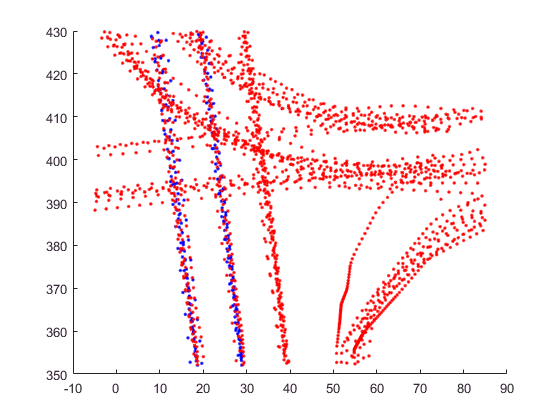

num_of_test_trajs = 10;
num_of_train_trajs = 10;
start_time = 10;
end_time = 50;

% Euclidean Distances
% 3-D matrices
error_gp1 = zeros(number_of_clusters,num_of_test_trajs, end_time);
error_gp2 = zeros(number_of_clusters,num_of_test_trajs, end_time);
error_dyn = zeros(number_of_clusters,num_of_test_trajs, end_time);
erro_ave_gp = zeros(number_of_clusters,num_of_test_trajs,end_time);
error_ave_gp_dyn = zeros(number_of_clusters,num_of_test_trajs,end_time);
error_ave_gp2_dyn = zeros(number_of_clusters,num_of_test_trajs,end_time);

for cluster = 1:number_of_clusters
    cluster
    if cluster == 4 || cluster == 5
        continue;
    end
    temp = [];
    temp = train_clustering(train_clustering(:,27) == cluster, :);
    unique_IDs = unique(temp(:,1));
    numOfVeh = size(unique_IDs, 1);
    
    
    start_traj = num_of_train_trajs + 1;
    end_traj = num_of_test_trajs + num_of_train_trajs;
    
    for i = start_traj : min(end_traj,numOfVeh) % trajectories from each cluster for testing
        % preparing the test traj
        test = [];
        test= temp(temp(:,1) == unique_IDs(i),:);
        scatter(test(:,5),test(:,6), 'b.');
        hold on;
        
        steps = size(test,1);
        steps = min(end_time,steps);
        if size(test,1) < (start_time + 1)
            continue
            % go to the next traj
        end
        
        % maneuver selection
        p_model = zeros(1,number_of_clusters);
        p_model(4) = Inf;
        p_model(5) = Inf;
        for c = 1:number_of_clusters
            if c == 5 || c == 4
                continue;
            end
            % preparing train data of cluster c
            temp_c = train_clustering(train_clustering(:,27) == c, :);
            unique_IDs_c = unique(temp_c(:,1));
            numOfVeh_c = size(unique_IDs_c, 1);
            train = [];
            for j =1:min(num_of_train_trajs,numOfVeh_c)
                train= [train;temp_c(temp_c(:,1) == unique_IDs_c(j),:)];
            end
            scatter(train(:,5),train(:,6), 'r.');
            hold on;
            %
            [m_vx,s_vx]= gp(hyp_vx(c), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25),test(1:start_time,5:6));
            [m_vy,s_vy] = gp(hyp_vy(c), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26),test(1:start_time,5:6));
            
            % Initialization of position, velocity and acceleration
            p = [test(1,5),test(1,6)];
            for j = 2:start_time
                p = Project(p,[m_vx(j-1),m_vy(j-1)]);
                %calculating Euclidean distances
                error = EuclideanD(p, test(j,5:6));
                p_model(c) = p_model(c) + error;
            end
        end
        [val index] = min(p_model);
        selected_cluster = index
        
        [m_vx,s_vx]= gp(hyp_vx(selected_cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25),test(1:steps,5:6));
        [m_vy,s_vy] = gp(hyp_vy(selected_cluster), @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26),test(1:steps,5:6));
        
        
        % Initialization of position, velocity and acceleration
        p = [test(start_time,5),test(start_time,6)];
        v = [test(start_time,25),test(start_time,26)];
        a = [test(start_time,25) - test(start_time - 1,25) , test(start_time,26) - test(start_time - 1,26)];
        
        p_gp_1 = p;
        p_gp_2 = p;
        p_dyn = p;
        v_dyn = v;
        
        p_ave_gp = p;
        p_ave_gp_dyn = p;
        p_ave_gp2_dyn = p;
        
        for j = start_time:steps
            p_gp_2 = Project(p_gp_2,[m_vx(j),m_vy(j)]);
            [p_dyn,v_dyn] =  Project(p_dyn,v_dyn,a);
            
            %calculating Euclidean distances
            error_gp2(cluster,i-num_of_train_trajs,j) = EuclideanD(p_gp_2, test(j,5:6));
            error_dyn(cluster,i-num_of_train_trajs,j) = EuclideanD(p_dyn, test(j,5:6));
        end
        
    end
    hold off;
    
end

# Mean Euclidean Distance Calculation

figure
% error_gp1(error_gp1 == 0) = NaN;
error_gp2(error_gp2 == 0) = NaN;
error_dyn(error_dyn == 0) = NaN;
% erro_ave_gp(erro_ave_gp == 0) = NaN;
% error_ave_gp_dyn(error_ave_gp_dyn == 0) = NaN;
% error_ave_gp2_dyn(error_ave_gp2_dyn == 0) = NaN;

n = number_of_clusters * num_of_test_trajs;
% sd = std(reshape(error_gp1, n, end_time), 'omitnan');
% errorbar(mean(reshape(error_gp1, n, end_time), 'omitnan'),sd,'-s','MarkerSize',5);
% hold on;
sd = std(reshape(error_gp2, n, end_time), 'omitnan');
errorbar(mean(reshape(error_gp2, n, end_time), 'omitnan'),sd,'-s','MarkerSize',5);
hold on;
sd = std(reshape(error_dyn, n, end_time), 'omitnan');
errorbar(mean(reshape(error_dyn, n, end_time), 'omitnan'),sd,'-s','MarkerSize',5);
hold on;
% sd = std(reshape(erro_ave_gp, n, end_time), 'omitnan');
% errorbar(mean(reshape(erro_ave_gp, n, end_time), 'omitnan'),sd);
% hold on;
% sd = std(reshape(error_ave_gp_dyn, n, end_time), 'omitnan');
% errorbar(mean(reshape(error_ave_gp_dyn, n, end_time), 'omitnan'),sd);
% hold on;
% sd = std(reshape(error_ave_gp2_dyn, n, end_time), 'omitnan');
% errorbar(mean(reshape(error_ave_gp2_dyn, n, end_time), 'omitnan'),sd);
hold off;

% legend('gp1', 'gp2','dynamic','ave gp1 gp2', 'ave gp1 gp2 dyn', 'ave gp2 dyn');
legend('gp', 'dynamic');

## RMSE Error Calculation

error_gp1_2 = error_gp1 .^ 2;
error_gp2_2 = error_gp2 .^ 2;
error_dyn_2 = error_dyn .^ 2;
erroerro_ave_gp_2 = erro_ave_gp .^ 2;
error_ave_gp_dyn_2 = error_ave_gp_dyn .^ 2;
error_ave_gp2_dyn_2 = error_ave_gp2_dyn .^ 2;

RMSE_gp1 = sqrt(mean(reshape(error_gp1_2, n, end_time), 'omitnan'));
RMSE_gp2 = sqrt(mean(reshape(error_gp2_2, n, end_time), 'omitnan'));
RMSE_dyn = sqrt(mean(reshape(error_dyn_2, n, end_time), 'omitnan'));
plot(RMSE_gp2);
hold on;
plot(RMSE_dyn);
legend('gp','dynamic');